## Initialize the class

Initialize with an equilibrium point $x_{eq}$, a tolerance $\Delta x$. The two vectors must have the same size. You can change the default values for the solver used and the verbose parameter of the optimization calls.

toy = SOStab([0;0],[1;1]);
%toy.solver = 'mosek';
%toy.verbose = 2;

## Define the dynamic of the system

Define $f$ such that $\dot{x} = f(x)$ the vector must have the same size as $x$. The property "x" of the system is a YALMIP sdpvar, which is a symbolic representation of the state variable. It has the same size as the problem.

For example, here we implement $f$ such that $\dot{x} = (x^\top x - 0.25)x$.

toy.dynamics = (toy.x'*toy.x - 0.25)*toy.x;

## Solve the outer approximation problem

Solve the outer approximation of the finite horizon ROA for a target set $K = \{ x : \|x - x_{eq} \| \leq \epsilon \}$ with $\epsilon = 0.1$ and a horizon $T=20$. The degree of the polynomials is defined by $d=6$. $d$ above 20 is useless and for high dimensions, a standard computer RAM can't cope with $d$ above 10.

toy.SoS_out(6,20,0.1);

-------------------------------------------------------------------------
YALMIP SOS module started...
-------------------------------------------------------------------------
Detected 292 parametric variables and 3 independent variables.
Detected 0 linear inequalities, 0 equality constraints and 0 LMIs.
Using kernel representation (options.sos.model=1).
Creating SOS-description 1/12
Initially 6 monomials in R^2
Removing large/small............Keeping 6 monomials (0sec)
Newton polytope (0 LPs).........Keeping 6 monomials (0.02sec)
Finding symmetries..............Found no symmetries (0sec)
Creating SOS-description 2/12
Initially 10 monomials in R^2
Removing large/small............Keeping 10 monomials (0sec)
Newton polytope (0 LPs).........Keeping 10 monomials (0sec)
Finding symmetries..............Found no symmetries (0sec)
Creating SOS-description 3/12
Initially 6 monomials in R^2
Removing large/small............Keeping 6 monomials (0sec)
Newton polytope (0 LPs).........Keeping 6 mono

## Solve the inner approximation problem

Solve the inner approximation of the RoA. Note that the results of this approximation are very sensitive to the relative size of the sets and the degree of the polynomials. You can check the relevance of the results by verifying the coefficients of w*w*. If they are null for most of them, then this means that the solver was not able to find the optimum of the problem. You can try to increase the size of the target set or the degree of the polyomials.

toy.SoS_in(6,20,0.1);

-------------------------------------------------------------------------
YALMIP SOS module started...
-------------------------------------------------------------------------
Detected 462 parametric variables and 3 independent variables.
Detected 0 linear inequalities, 0 equality constraints and 0 LMIs.
Using kernel representation (options.sos.model=1).
Creating SOS-description 1/18
Initially 6 monomials in R^2
Removing large/small............Keeping 6 monomials (0sec)
Newton polytope (0 LPs).........Keeping 6 monomials (0.01sec)
Finding symmetries..............Found no symmetries (0sec)
Creating SOS-description 2/18
Re-using all candidate monomials (same problem structure)
Creating SOS-description 3/18
Re-using all candidate monomials (same problem structure)
Creating SOS-description 4/18
Initially 10 monomials in R^2
Removing large/small............Keeping 10 monomials (0sec)
Newton polytope (0 LPs).........Keeping 10 monomials (0sec)
Finding symmetries..............Found no symmet

witoy = value(toy.wcoef_inner);
witoy(1) = witoy(1)-1;
if witoy'*witoy > 0.00001
    toy.plot_roa(1,2,'inner',0,"x","y");
else
    disp("w not relevant")
end

w not relevant


## Plot the ROA

Plot the projection of the ROA on two dimensions (for the last calculated approximation).

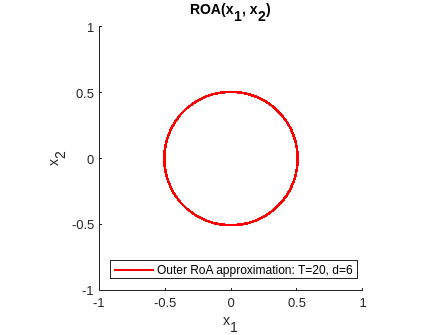

clf;
toy.plot_roa(1,2,'outer');
axis('equal');

## Plot the surface of $w$

Plot the surface of $w$ for the last calculated inner or outer approximation.

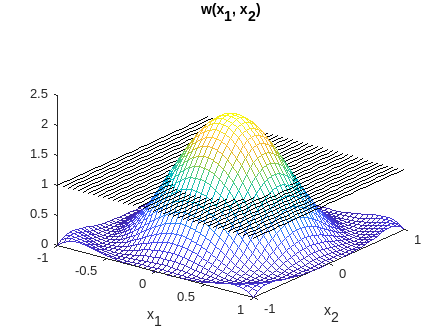

toy.plot_w(1,2, 'o');

## Other examples of dynamics

See the Readme for more explanation on the corresponding dynamics.

### Van der Pol oscillator

clf;
vdp = SOStab([0;0],[1.1;1.1]);
vdp.dynamics = [-2*vdp.x(2); 0.8*vdp.x(1) + 10*(vdp.x(1)^2-0.21)*vdp.x(2)];
vdp.SoS_out(12,1,0.5);

-------------------------------------------------------------------------
YALMIP SOS module started...
-------------------------------------------------------------------------
Detected 1734 parametric variables and 3 independent variables.
Detected 0 linear inequalities, 0 equality constraints and 0 LMIs.
Using kernel representation (options.sos.model=1).
Creating SOS-description 1/12
Initially 21 monomials in R^2
Removing large/small............Keeping 21 monomials (0.02sec)
Newton polytope (0 LPs).........Keeping 21 monomials (0.02sec)
Finding symmetries..............Found no symmetries (0sec)
Creating SOS-description 2/12
Initially 28 monomials in R^2
Removing large/small............Keeping 28 monomials (0sec)
Newton polytope (0 LPs).........Keeping 28 monomials (0sec)
Finding symmetries..............Found no symmetries (0sec)
Creating SOS-description 3/12
Initially 21 monomials in R^2
Removing large/small............Keeping 21 monomials (0sec)
Newton polytope (0 LPs).........Keepi

vovdp = value(vdp.vcoef_outer);
wovdp = value(vdp.wcoef_outer);
vdp.plot_roa(1,2,'outer',1,"x_1","x_2");
vdp.SoS_in(12,1,0.5);

-------------------------------------------------------------------------
YALMIP SOS module started...
-------------------------------------------------------------------------
Detected 3010 parametric variables and 3 independent variables.
Detected 0 linear inequalities, 0 equality constraints and 0 LMIs.
Using kernel representation (options.sos.model=1).
Creating SOS-description 1/18
Initially 21 monomials in R^2
Removing large/small............Keeping 21 monomials (0sec)
Newton polytope (0 LPs).........Keeping 21 monomials (0sec)
Finding symmetries..............Found no symmetries (0sec)
Creating SOS-description 2/18
Re-using all candidate monomials (same problem structure)
Creating SOS-description 3/18
Re-using all candidate monomials (same problem structure)
Creating SOS-description 4/18
Initially 28 monomials in R^2
Removing large/small............Keeping 28 monomials (0sec)
Newton polytope (0 LPs).........Keeping 28 monomials (0sec)
Finding symmetries..............Found no symme

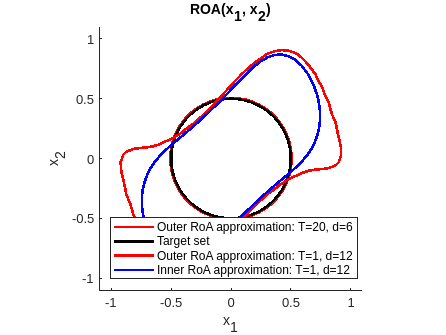

vivdp = value(vdp.vcoef_inner);
wivdp = value(vdp.wcoef_inner);
wivdp(1) = wivdp(1)-1;
if wivdp'*wivdp>0.00001
    vdp.plot_roa(1,2,'inner',0,"x_1","x_2");
end

### Scaled pendulum

clf;
pen = SOStab([0;1;0],[1;1;1],[1,2]);
pen.dynamics = [-2*pen.x(1)*pen.x(2)^2;2*pen.x(1)^2*pen.x(2);0];
pen.SoS_out(6,40,0.5);

-------------------------------------------------------------------------
YALMIP SOS module started...
-------------------------------------------------------------------------
Detected 819 parametric variables and 4 independent variables.
Detected 0 linear inequalities, 0 equality constraints and 0 LMIs.
Using kernel representation (options.sos.model=1).
Creating SOS-description 1/15
Initially 10 monomials in R^3
Removing large/small............Keeping 10 monomials (0sec)
Newton polytope (0 LPs).........Keeping 10 monomials (0sec)
Finding symmetries..............Found no symmetries (0sec)
Creating SOS-description 2/15
Initially 20 monomials in R^3
Removing large/small............Keeping 20 monomials (0sec)
Newton polytope (0 LPs).........Keeping 20 monomials (0sec)
Finding symmetries..............Found no symmetries (0sec)
Creating SOS-description 3/15
Initially 10 monomials in R^3
Removing large/small............Keeping 10 monomials (0sec)
Newton polytope (0 LPs).........Keeping 10 m

vopen = value(pen.vcoef_outer);
wopen = value(pen.wcoef_outer);
pen.plot_roa([1,2,1],3,'outer',1,"\theta","\omega");
axis('square');
pen.SoS_in(6,40,0.5);

-------------------------------------------------------------------------
YALMIP SOS module started...
-------------------------------------------------------------------------
Detected 1274 parametric variables and 4 independent variables.
Detected 0 linear inequalities, 0 equality constraints and 0 LMIs.
Using kernel representation (options.sos.model=1).
Creating SOS-description 1/23
Initially 10 monomials in R^3
Removing large/small............Keeping 10 monomials (0sec)
Newton polytope (0 LPs).........Keeping 10 monomials (0sec)
Finding symmetries..............Found no symmetries (0sec)
Creating SOS-description 2/23
Re-using all candidate monomials (same problem structure)
Creating SOS-description 3/23
Re-using all candidate monomials (same problem structure)
Creating SOS-description 4/23
Re-using all candidate monomials (same problem structure)
Creating SOS-description 5/23
Initially 20 monomials in R^3
Removing large/small............Keeping 20 monomials (0sec)
Newton polytope (0

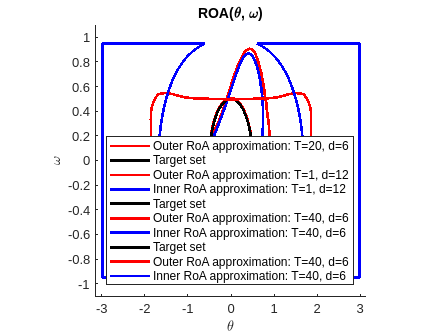

if double(pen.wcoef_outer(abs(double(pen.wcoef_outer)) > 0.00001))
    vipen = value(pen.vcoef_inner);
    wipen = value(pen.wcoef_inner);
    pen.plot_roa([1,2],3,'inner',0,"\theta","\omega");
else 
    print("w not relevant");
end

### 3 bus power system

clf;
eq = [sin(0.02);cos(0.02);sin(0.06);cos(0.06);0;0];
dev = [1;1;1;1;pi;pi];
ang_ind = [1,2;3,4];
pow_sys = SOStab(eq,dev,ang_ind);
pow_sys.dynamics = [pow_sys.x(5)*pow_sys.x(2);-pow_sys.x(5)*pow_sys.x(1);...
    pow_sys.x(6)*pow_sys.x(4);-pow_sys.x(6)*pow_sys.x(3);
    -pow_sys.x(1)-0.5*(pow_sys.x(1)*pow_sys.x(4)-pow_sys.x(2)*pow_sys.x(3))-0.4*pow_sys.x(5);
    -0.5*pow_sys.x(3)+0.5*(pow_sys.x(1)*pow_sys.x(4)-pow_sys.x(2)*pow_sys.x(3))-0.5*pow_sys.x(6)+0.05];
pow_sys.SoS_out(6,8,0.1);
vopow = value(pow_sys.vcoef_outer);
wopow = value(pow_sys.wcoef_outer);
pow_sys.plot_roa([1,2],[3,4],'o','1',"\theta_1","\theta_2");